# Sound Waves Produced from the Grand Piano

### Introduction/ Background

The music we hear from instruments is produced from the vibration of air particles through the air in the form of waves. More specifically, the sound waves produced are classified as mechanical longitudinal or compression waves since the particles vibrate in the same direction as the motion of the wave. The difference between random noise and music is the irregular waves of differing frequencies and wavelengths present in noise versus the regular patterns that occur in music. The sound waves produced from instruments can be affected by the different ways an instrument, such as the piano, is played. For instance, the piano has many different keys, octaves, notes, and chords that can be played, which affect the sound waves produced and ultimately cause us to hear a certain sound. The loudness and pitch of music is where we can detect the differences in the music sound waves.

Music is present in all cultures, all around the world so it is interesting to see music at its core and understand the way it works. The physics behind music and noise in general is interesting to learn what is pleasant sounding and  enjoyab;e and how when particles vibrate the right way in a uniform pattern, it can create beautiful harmonious sounds. It also interesting to look at the science behind music since these sound waves that we hear can affect us psychologically, altering our moods.

### Standing Waves/ Fundamental Wave

Musical tones from instruments are produced from standing waves. Standing waves are created when two waves with the same frequency and wavelength reflect back in the same medium, reinforcing each other. In standing waves there are parts of the wave that appear to not move at all, called nodes, and parts of the wave that move between the maximum and minimum amplitude, called antinodes. When the waves are reflected back into each other, the waves are reinforced, increasing the placement of the antinodes and making the maximum and minimum greater.

The longest wave that can be produced is called the fundamental. Harmonics of the fundamental wave are called overtones and are integer multiples of the fundamental frequency. The overtones are classified as the order of harmonic, meaning the fundamental frequency is the first harmonic, the first overtone is the second harmonic, the second overtone is the third harmonic, and so on. The length of the fundamental wave is the longest wave that can be produced in the container and the overtones are in relation to that length. For instance, for the first overtone, the waves are half the length of the fundamental, and for the second overtone, the waves are a third of the fundamental. This directly affects the pitch of the note since the number of waves, or frequency, increases. As the frequency of the waves increases, the pitch increases. Therefore, the higher the overtone, the higher the pitch of the note.

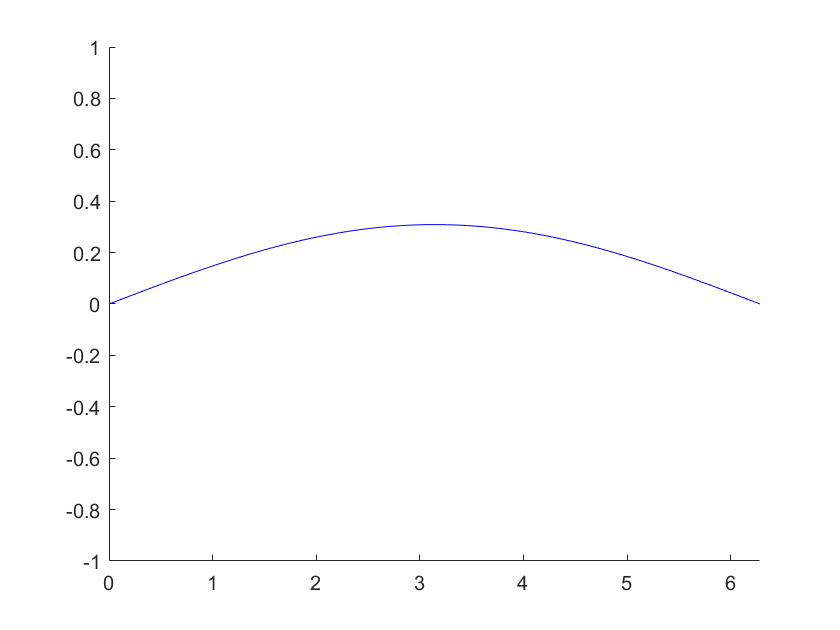

%run for animation
%fundamental frequency, first harmonic
h = figure;
nodes = .5;
x = 0:.01:((360/180)*pi);
axis([0 2*pi -1 1])
ax = gca;
ax.NextPlot = 'replaceChildren';
loops = 40;
M(loops) = struct('cdata',[],'colormap',[]);
h.Visible = 'off';
for j = 1:loops
    y = sin(j*pi/10);
    plot(x,y*sin(nodes*x),'b');
    drawnow
    M(j) = getframe;
end

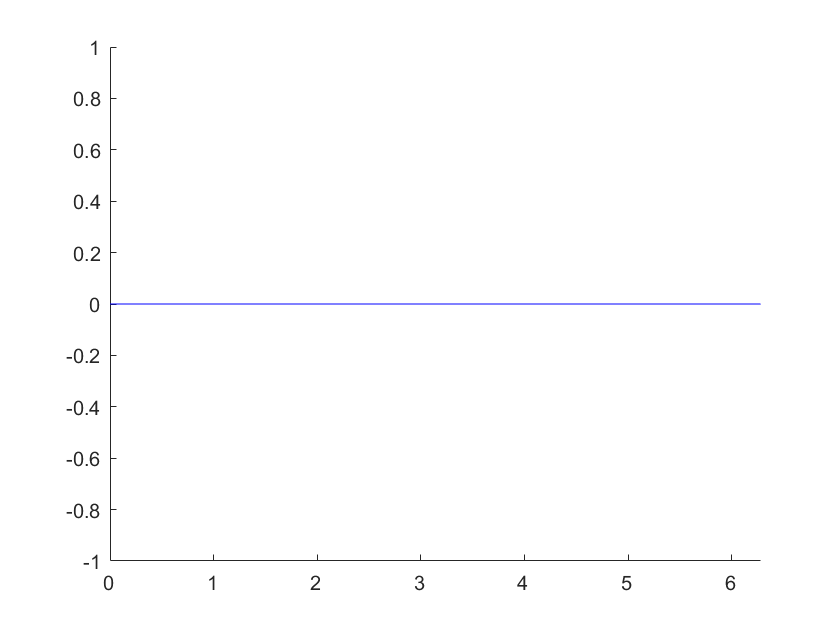

h.Visible = 'on';
movie(M)

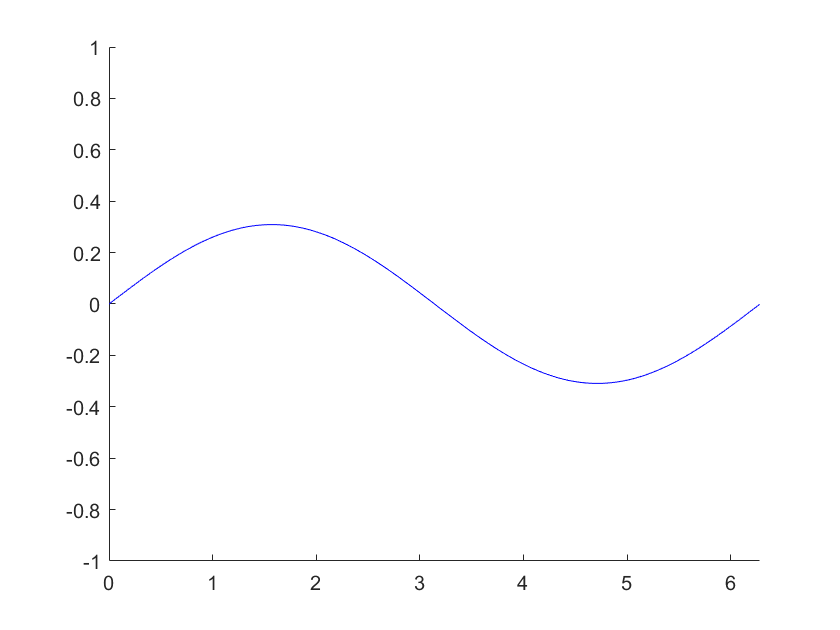

%first overtone, second harmonic
h = figure;
nodes = 1;
x = 0:.01:((360/180)*pi);
axis([0 2*pi -1 1])
ax = gca;
ax.NextPlot = 'replaceChildren';
loops = 40;
M(loops) = struct('cdata',[],'colormap',[]);
h.Visible = 'off';
for j = 1:loops
    y = sin(j*pi/10);
    plot(x,y*sin(nodes*x),'b');
    drawnow
    M(j) = getframe;
end

h.Visible = 'on';
movie(M)

### Effects on the Sinusoidal Equation

The equation of the basic note that you hear when an instrument is being played is y= Asin(B(2Pi(t)+ C)). The different parameters represent different alterations of the sound waves. The variable “A” represents amplitude, “B” represents frequency, and “C” represents its phase shift.

Amplitude is the intensity or loudness of a musical note. When A is changed, the amplitudes of the maximum and minimum change, while the frequency or pitch remains constant. As a result, the displacement of the antinodes of the waveis changed. The variable C when changed does not have an effect on A or B, so the amplitude and pitch remain constant. When the value of C is altered, the only thing affected is the phase of the sine waves. Therefore the change in C represents a delay of a note. Although not implemented in the function musicgraph, it is important to consider since it can change the timbre of a note played when there is a summation of equations of notes. When looking at B, we can consider the graphs with a frequency of 440, which is the fourth octave of A, versus 880, which is the fifth octave of A. Since the fifth octave of A is twice the frequency of the fourth octave of A, there are two cycles of the fifth for every cycle of the fourth. Frequency represents the pitch of a musical note so when you see the differing frequencies, this means that the pitch of the fourth octave is higher than the pitch of the fifth octave.

The variable B is important to consider since when “tuning” an instrument. When a piano is being tuned, the strings are tuned to the standard pitch of A440, or A above middle C. Over time, the strings of a piano stretch which ultimately change the tune of the different notes, so the piano strings need to be adjusted in order to fix the pitch of the different keys. Therefore, when an instrument is “out of tune”, the pitch is either too high or too low and the length of the strings needs to be adjusted accordingly. This idea can be applied to other string instruments as well, such as the violin or guitar, where the strings are altered in order to get the right pitch.

%open finalapp

### Piano Notes and Octaves

Sound waves are changed according to the different note and the octave of that note being played. On a piano, the notes range from A to F, with sharps and flats of each note. However, the equation of a flat note is the same as the sharp of the letter of the note below it, meaning that B flat is the same value as A#. Also, on a piano, there is no black key between C and B or E and F meaning that B# or E# are not present.

In the function MUSICGRAPH, the equation used to represent the notes played is y = A(sin(a*b*x)+c). A(amplitude) and c(phase change) are kept constant so that it is emphasized how the notes and octaves of the notes affect the pitch of the sound waves that are produced from a piano. The variable a in the function MUSICGRAPH is multiplied separate from the variable b since the variable a represents the different octave of the note being played while b is representative of the different note being played. 

The value of a in the function is found by finding the number that is attached to the note, which is representative of the octave of the note, and then multiplying the lowest frequency played on a piano by 2 raised to the octave. The lowest note played is A0 which has a frequency of 27.5 so that is the value that the other notes are based off of. The value of b in the function is found by finding what note is being played and if it is a sharp of the note, meaning it has the # symbol alongside the letter of the note. Since keyboard instruments, such as the piano, are played according to the equal temperament scale, the note being played corresponds to how many times the twelfth root of two needs to be multiplied to the basic frequency of 2 pi. The function finds what note is being played and then multiplies the value b by the twelfth root of 2 the correct number of times and if it is a sharp note, b is multiplied by the twelfth root of 2 an additional time.

Therefore, if the note C4 is inputted and then C5 is inputted, the value of b is constant but the value of a is different, while if C4 is inputted and then D4 is inputted, the value of a is constant but the value of b is different. Also, from the graphs it is evident that as you move up through the notes and octaves, frequency increases.

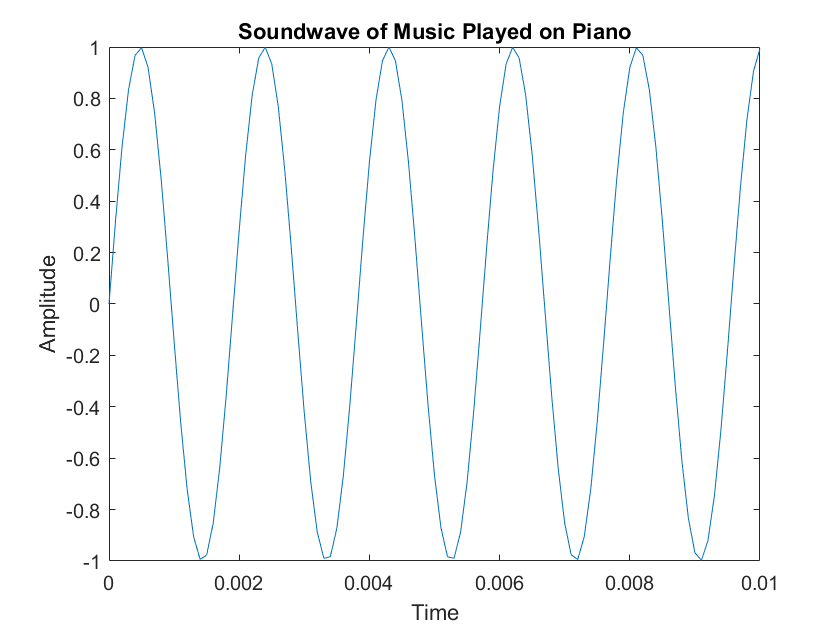

   440

    7.4719



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4")

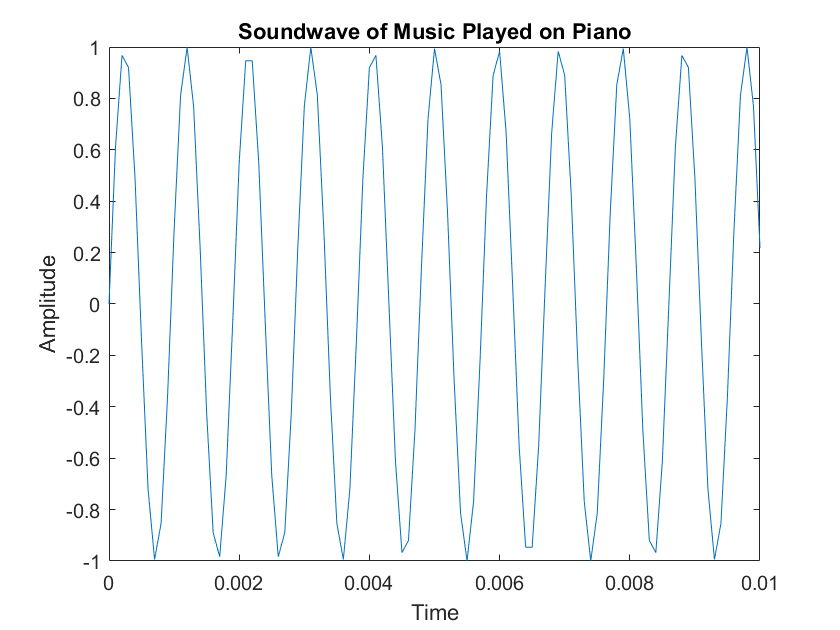

   880

    7.4719



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C5")

   440

    7.4719



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4")

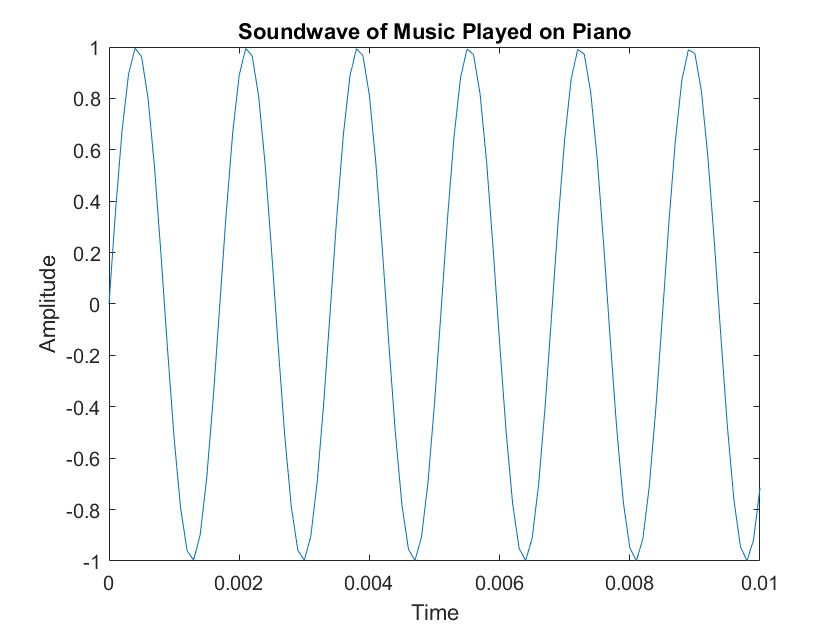

   440

    8.3869



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("D4")

### Chords

The function also produces graphs of chords played on a piano. When a set of notes, or a chord, is played, the sound waves interact with each other and the equations of each note is summed together. The mathematician, Jean-Baptiste Joseph Fourier, created a solution for any signal that behaves like a wave called the Fourier transform that takes a wave function and describes it as the sum of the different sine waves. A Fourier analysis therefore shows that the chords played all have sinusoidal equations at its base. Usually the Fourier analysis is used for signal processing, but it essentially means the simplification of a complicated equation into basic sine and cosine functions. For instance, when comparing the three different sound waves of the graph of A4C4 and the graphs of A4 and C4 separately, it is evident that although A4C4 is much more complex, when looking at its components of the notes A4 and C4, one can see that it is made up of basic sine waves. It is also important to note that the chord has double the amplitude of the singular notes, showing again that the chord is the sum of the notes played. This is significant since it shows that every acoustic has regularities within it and is essentially made up of simple, regular sine waves.

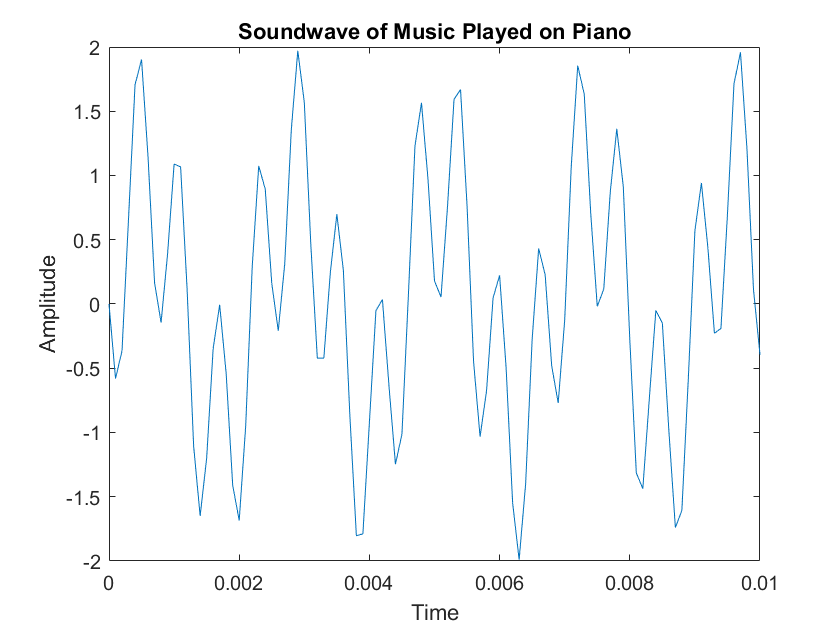

        7040

    7.4719

     1     2

    "A4"    "C4"



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("A4C4")

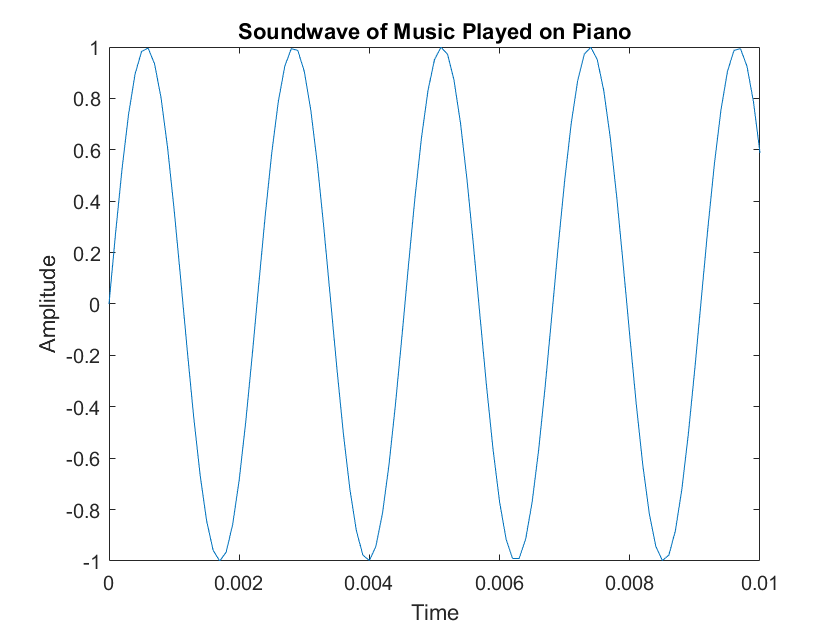

   440

    6.2832



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("A4")

   440

    7.4719



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4")

### Consonant v. Disonant Chords

Some chords sound more pleasant while others produce a harsher sound. When a set of chords sound harmonious they are called consonant chords and when the sounds are more clashing, they are called dissonant chords. Examples of consonant chords are notes with simple frequency ratios. This means that the ratio between the frequency of notes is 1:2, 2:3, or 3:4, while very dissonant sounding ratios are 15:16 or 32:45. For example, the notes C and G is a stable harmony, also called perfect fifth, while C and D are an unstable harmony, also called major second. Adjacent notes, like C and C#, are harsh and unpleasant, while notes an octave apart like C3 and C4 are consonant and pleasant. When looking at the graphs it is seen that the more pleasant chord have a more sinusoidal shaped graph while the more dissonant, harsh sounding chords stray further from the sine wave. The dissonant sound waves are more irregular while the consonant sound waves have a more regular pattern of waves.

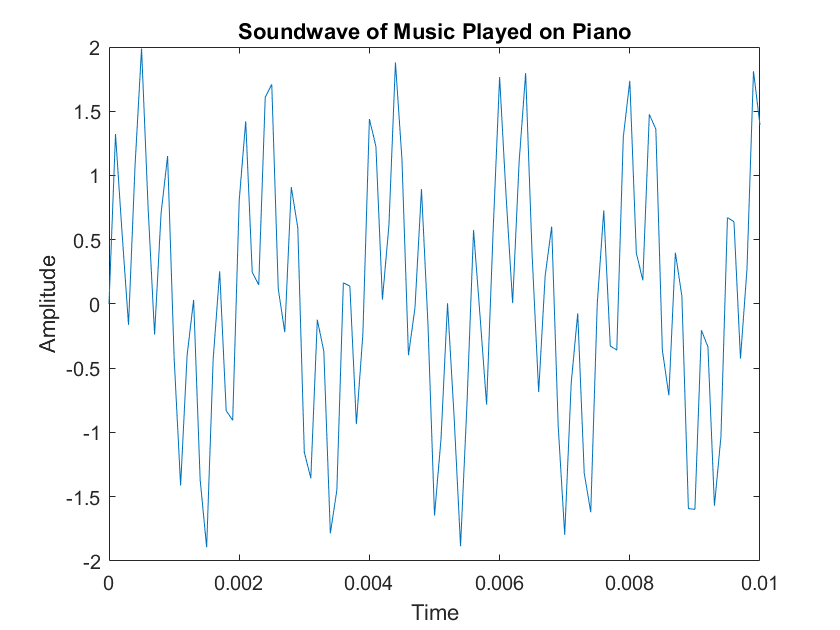

        7040

   11.1950

     1     2

    "C4"    "G4"



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4G4")

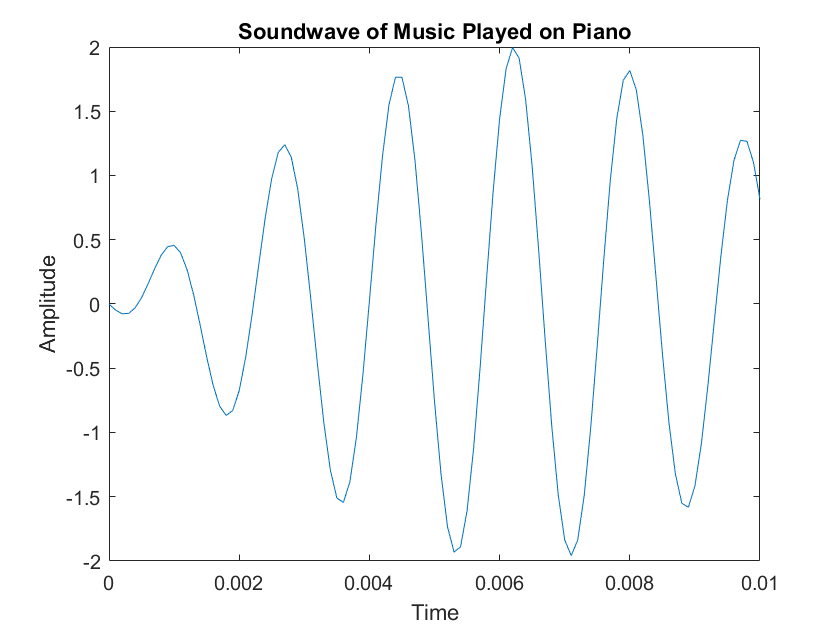

        7040

    8.3869

     1     2

    "C4"    "D4"



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4D4")

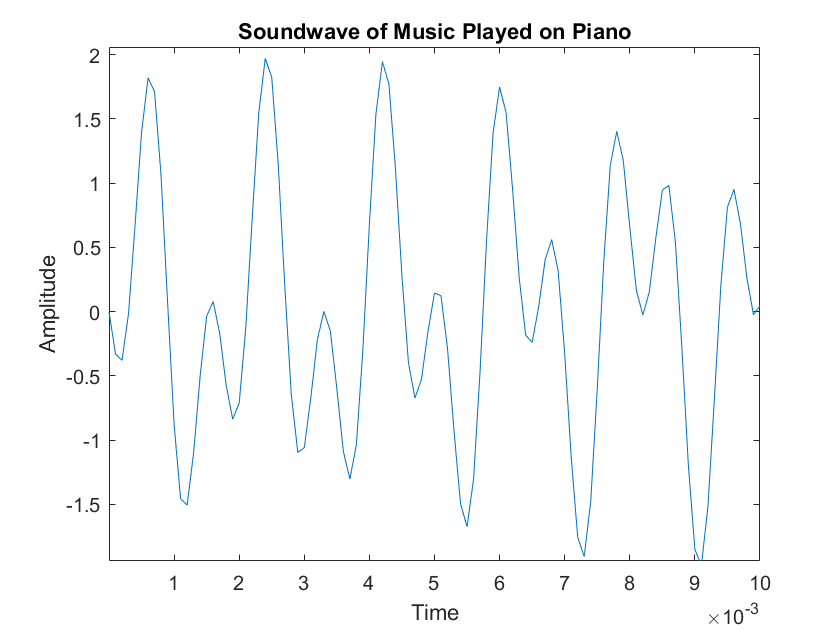

        7040

    7.9162

     1     2

    "C4"    "C#4"



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C4C#4")

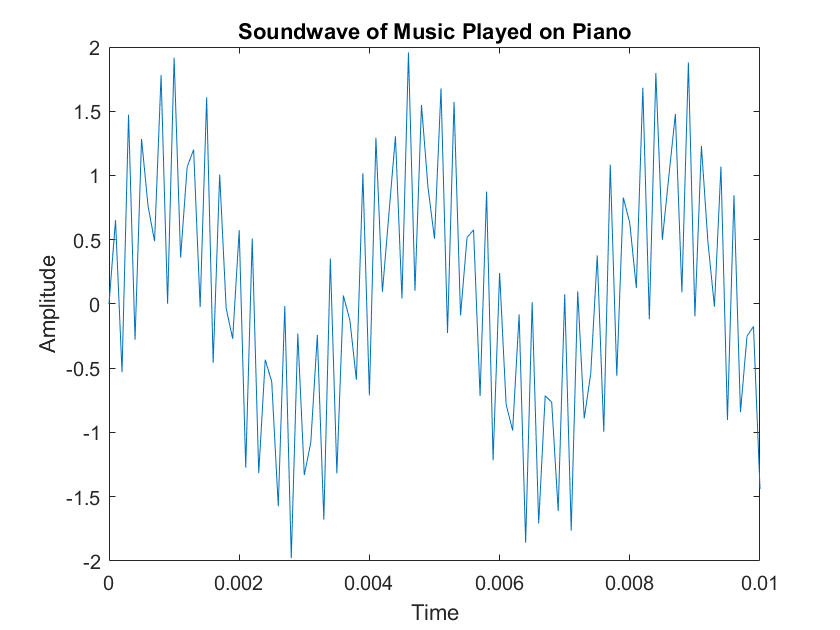

        3520

    7.4719

     1     2

    "C3"    "C4"



ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×101 double]
              YData: [1×101 double]
              ZData: [1×0 double]

  Show all properties


musicgraph("C3C4")

function [graph,a,b] = musicgraph(music)
%MUSICGRAPH returns the graph of music played on a piano
%   The function takes the input of all notes played and produces a graph
%   of the soundwaves of the chord or key played
x = 0:0.0001:.01;
%the lowest frequency on a piano is of note A0 which is 27.5 Hz
a = 27.5;
allnotes=["A" "A#" "B" "C" "C#" "D" "D#" "E" "F" "F#" "G" "G#"];
if strlength(music)>3
%if length >3, multiple keys played
%need to separate music then add equations together
    notes = regexp(music,'\w\d|\w#\d','match');
    y = 0;
    h = size(notes);
    %as you go up each note, the frequency is multiplied by the twelfth
    %root of two
    for i = 1:(h(2))
       n = find(notes{i}(1) == allnotes);
       if n == 1
           b = 2*pi;
       else
           b = (2*pi)*(1.05946.^(n-1));
       end
       if notes{i}(2)=="#"
           %sharp note so b needs to be multiplied by 1.05946 again
           b = b*1.05946;
           octave = str2double(notes{i}(3));
       else
           octave = str2double(notes{i}(2));
       end
       %octave is the number inputted and effects f by multiplying a by 2
       %raised to the octave
       a = a*(2^octave);
       eq = sin(a*b*x);
       %when multiple keys played equations of each note are added together
       y = y + eq;
       
    end
    graph = plot(x,y);
    xlabel('Time');
    ylabel('Amplitude');
    title('Soundwave of Music Played on Piano');
    disp(a)
    disp(b)
    disp(size(notes))
    disp(notes)

else
    %if only one key is played
    sepnote = split(music,"");
    %gives "" at beginning and end
    n = find(sepnote(2) == allnotes);
       if n == 1
           b = 2*pi;
       else
           b = (2*pi)*(1.05946.^(n-1));
       end
       if sepnote(3)=="#"
           %it is a sharp note so b multiplied by 1.05946 again
           b = b*1.05946;
           octave = str2double(sepnote(4));
       else
           octave = str2double(sepnote(3));
       end
       a = a*(2^octave);
       y = sin(a*b*x);
       graph = plot(x,y);
       xlabel('Time');
       ylabel('Amplitude');
       title('Soundwave of Music Played on Piano');
       disp(a)
       disp(b)

end

end

### Conclusion

The music notes and chords we hear are distinguished by many different factors. Through the sound waves, the individual effects are able to be seen. The different frequencies of the sound waves that travel to our ears are affected firstly by the amount of keys played. As shown, if a chord of notes are played together, the equations are added together, altering the sound waves produced. The particular key played then changes the equation of the sound wave even more. The specific letter of the note played, if it is a sharp or flat note, and the octave of that note all contribute to the change in the graph of a sound wave from a simple sine wave. From these graphs, it is shown how the graphs we see correspond to the sounds we hear. As the octave increases, the pitch increases as seen in the increasing frequencies of the graphs. Also, as the notes go from A to F, the pitch increases, which is again shown through the increasing frequencies of the sine waves. As the amplitude increases, the antinodes, or maximums and minimums on the graph, also increases, showing how the notes become louder as the amplitude increases. All the information shown is in relation to the grand piano, which is a string instrument, but other instruments, such as the flute, which is a woodwind instrument, affects sound waves in a slightly different way. Also, playing multiple instruments together would significantly change the sound waves that we hear from music. Future studies could include the science behind how music and sound waves affect the brain. There are many psychological effects of hearing happy versus sad tunes in relation to the sound waves. The area of acoustics and the Fourier theorem/ analysis can be delved into much more and more information can be discovered. By reviewing the sound waves we hear, we can better understand music or noise in general and its effects.

### Sources:

Schmidt-Jones, C. (2006, August 24). *Standing Waves and Musical Instruments*. [https://www8.physics.utoronto.ca/~jharlow/teaching/everyday06/reading12.pdf](https://www8.physics.utoronto.ca/~jharlow/teaching/everyday06/reading12.pdf)

Lapp, D. (2002). The Physics of Music and Musical Instruments. In Wright Center for Innovative Science Education Tufts University (Ed.), *The Physics of Music and Musical Instruments* (pp. 1–110).[http://kellerphysics.com/acoustics/Lapp.pdf](http://kellerphysics.com/acoustics/Lapp.pdf)

Pritts, V. (2010). *Sine and Cosine Graph*. [https://trigfunctionsofmusic.weebly.com/](https://trigfunctionsofmusic.weebly.com/)

Southern State Community College. (2019). *Graphs of Musical Note Combinations*. [https://www.sscc.edu/home/jdavidso/music/musicnotes/musicnotes.html](https://www.sscc.edu/home/jdavidso/music/musicnotes/musicnotes.html)

The University of Georgia, & Dally, W. (2003). *The Ubiquitous Sine Function*. [http://jwilson.coe.uga.edu/EMT668/EMAT6680.2003.Su/Daly/Write_Ups/WR_1/Asmt_1.htm](http://jwilson.coe.uga.edu/EMT668/EMAT6680.2003.Su/Daly/Write_Ups/WR_1/Asmt_1.htm)

Jacqueline, R. (2015, January 2). *The Science Behind Piano Tuning*. [https://rjacqueline784.wordpress.com/2015/01/02/the-science-behind-piano-tuning/#:%7E:text=That%E2%80%99s%20the%20basis%20of%20piano%20tuning%2C%20and%20it,was%20a%20mainstream%20practice%20back%20in%20the%201800s](https://rjacqueline784.wordpress.com/2015/01/02/the-science-behind-piano-tuning/#:%7E:text=That%E2%80%99s%20the%20basis%20of%20piano%20tuning%2C%20and%20it,was%20a%20mainstream%20practice%20back%20in%20the%201800s)

Estrella, E. (2019, February 16). *Do Music Chord Frequencies Affect Human Moods?* LiveAbout. [https://www.liveabout.com/understanding-dissonant-and-consonant-chords-2456562](https://www.liveabout.com/understanding-dissonant-and-consonant-chords-2456562)

Evens, A. (2005). Sound and Noise. In *Sound Ideas: Music, Machines, and Experience* (pp. 1-25). University of Minnesota Press. Retrieved December 4, 2020. [http://www.jstor.org/stable/10.5749/j.cttttzbc.5](http://www.jstor.org/stable/10.5749/j.cttttzbc.5)